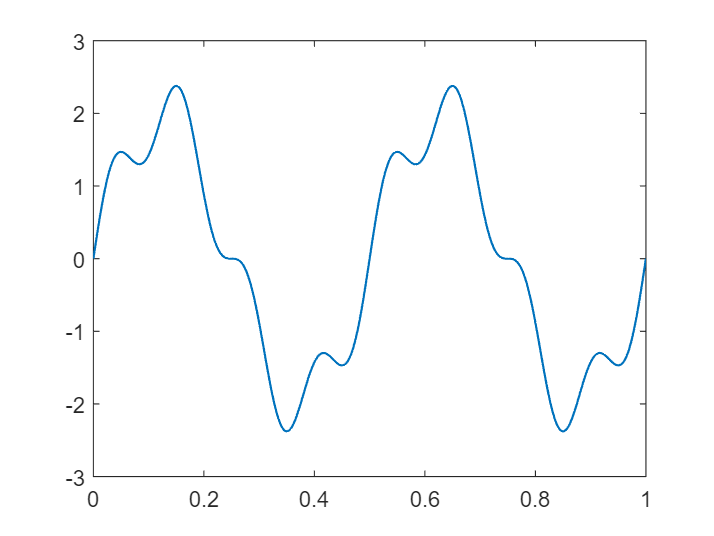

Fs = 1000; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Define the coefficients b1, b2, and b3
b1 = 2;
b2 = 0.5;
b3 = 0;
% Define the frequencies f1, f2, and f3 in Hz
f1 = 2;
f2 = 8;
f3 = 25;
% Create the signal y
y = b1*sin(2*pi*f1*t) + b2*sin(2*pi*f2*t) + b3*sin(2*pi*f3*t);



plot(t,y,'linewidth',1)
xlim([0,1])

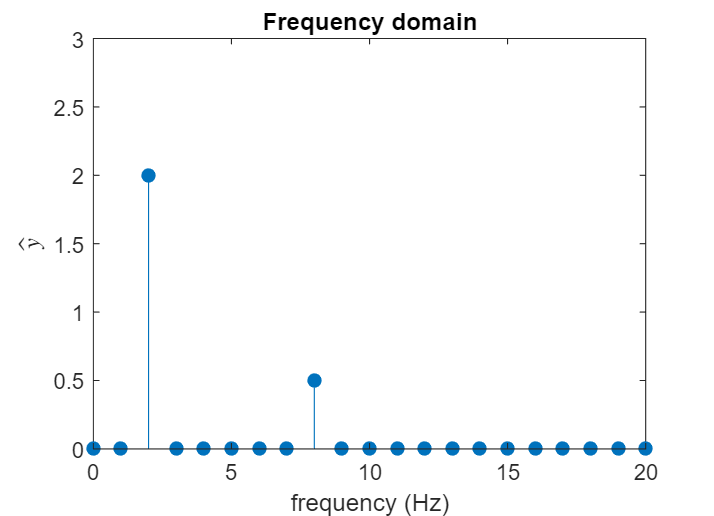




% Frequency domain
freq = 0:20;
ghat = zeros(1,numel(freq));
ghat(f1+1) = b1;
ghat(f2+1) = b2;


figure
stem(freq,ghat,"filled")
ylim([0,3])
title("Frequency domain")
xlabel("frequency (Hz)")
ylabel("$\hat{y}$","Interpreter","latex")